clear;
close all;
clc;

addpath('GSH\Tools\')
addpath('data\')

G = 6.6743e-11;
R_ref = 2440e3;
M_mercury = 3.285e23;
g_ref = G*M_mercury/R_ref^2

g_ref = 3.6827

% Create lat/lon grid
resolution = 10;
latLimT = [-90+(1/resolution/2) 90-(1/resolution/2) 1/resolution];
lonLimT = [1/resolution/2  360-(1/resolution/2) 1/resolution];
% lonLimT = [-180+1/resolution/2  180-(1/resolution/2) 1/resolution];

lonT = lonLimT(1):lonLimT(3):lonLimT(2);
latT = fliplr(latLimT(1):latLimT(3):latLimT(2));
LonT = repmat(lonT,length(latT),1);
LatT = repmat(latT',1,length(lonT));

% Read Gravity Spherical Harmonics
SC_data = readmatrix('cleaned_gsh.csv', OutputType='double');
% disp(SC_data);

L = max(SC_data(:,1));
clm = SC_data(:, 1:4);

% Convert to /S|C\ Triangle format
sc = clm2sc(clm);


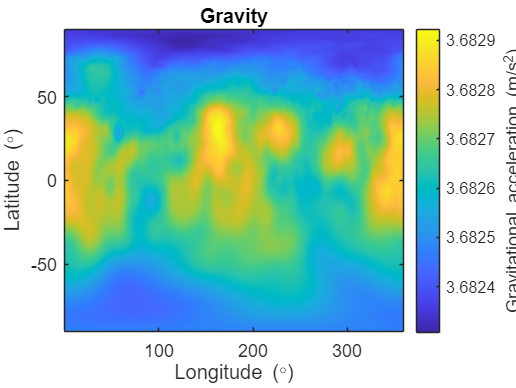

% Plot gravitational potential
% MIGHT NEED TO DO FREE AIR CORRECTION 2g/R*h
gravity_map_norm = GSHS(sc, lonT, 90-latT, 160);

gravity_map = (1+gravity_map_norm) * G*M_mercury/(R_ref^2);

gravity_anomaly_map = gravity_map_norm * G*M_mercury/(R_ref^2);

aa=12;
figure
imagesc(lonT,latT,gravity_map);cc=colorbar;
title('Gravity')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Gravitational acceleration (m/s^2)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

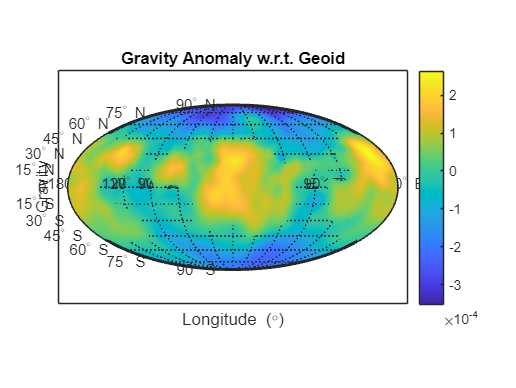


figure
axesm('mollweid', 'Frame', 'on', 'Grid', 'on', 'MeridianLabel', 'on', 'ParallelLabel', 'on')
setm(gca, 'MLabelParallel', 3)
geoshow(LatT, LonT, gravity_anomaly_map, 'DisplayType', 'surface')
title('Gravity Anomaly w.r.t. Geoid')
colorbar;
xlabel('Longitude (\circ)')
ylabel('Latitude (\circ)')
ylabel('Gravity')
set(gca, 'YDir', 'normal')


% light
% material(0.6*[1 1 1])
% axis normal
% view(3)


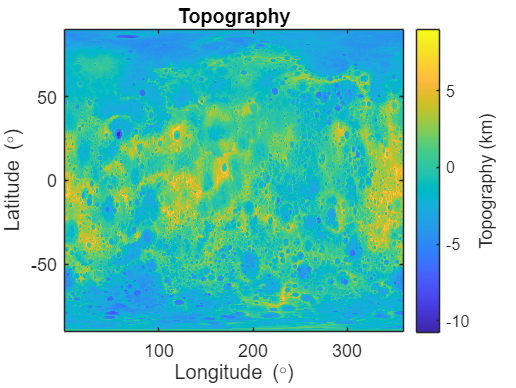

% Load topography
filename = 'mercury.tif';
% f = fopen(filename,'r','ieee-be');
% topo_map = fread(f,[360*250 Inf],'int16')';
% fclose(f); 

topo_map = imread(filename);

resized_topo_map = imresize(topo_map, [size(gravity_map, 1), size(gravity_map, 2)]);
resized_topo_map = double(resized_topo_map);


% Plot topography
figure
imagesc(lonT,latT,resized_topo_map./1e3);cc=colorbar;
title('Topography')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

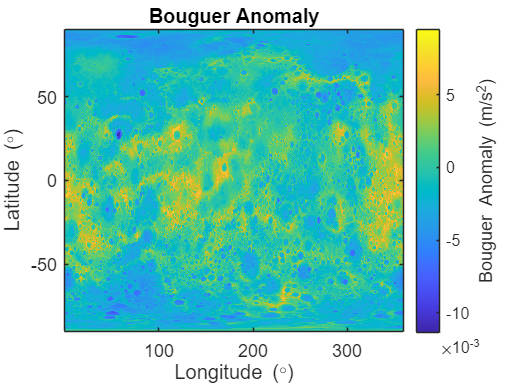

% Calculate bouguer anomaly
%% IS FREE AIR CORRECTIONNEEDED/APPLCIABLE??

rho_crust = 2540;
bouguer_correction = 2*pi*G*rho_crust*resized_topo_map;
% free_air_correction = 2*g_ref*resized_topo_map/R_ref;

% bouguer_anomaly = gravity_anomaly_map+free_air_correction-bouguer_correction;
% Added minus coz it looked bad
bouguer_anomaly=-(gravity_anomaly_map-bouguer_correction);
% Plot Bouguer anomaly
figure
imagesc(lonT,latT,bouguer_anomaly);cc=colorbar;
title('Bouguer Anomaly')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Bouguer Anomaly (m/s^2)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

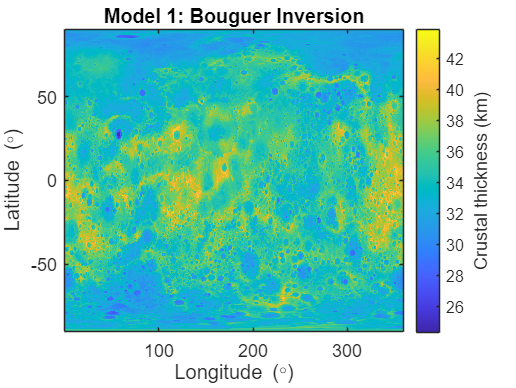

% Model 1: Bouguer Inversion
D_ref = 35e3; % km reference crustal thickness

deltaR1 = bouguer_anomaly/(2*pi*G*rho_crust);

figure
imagesc(lonT, latT,(D_ref+deltaR1)./1e3); cc=colorbar;
title('Model 1: Bouguer Inversion')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Crustal thickness (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

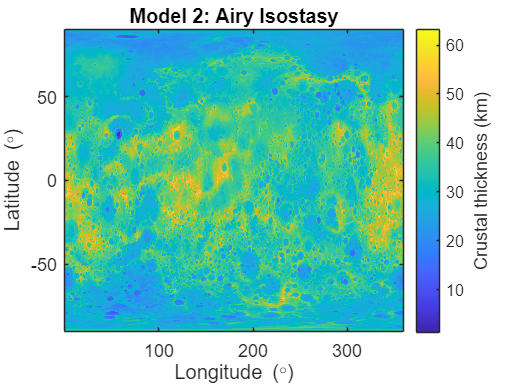

% Model 2: Airy Isostasy

rho_mantle = 3350;

deltaR2 = resized_topo_map*rho_crust/(rho_mantle-rho_crust);

figure
imagesc(lonT, latT, (D_ref+deltaR2)./1e3); cc=colorbar;
title('Model 2: Airy Isostasy')
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Crustal thickness (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

% Flexure

cs3 = GSHA(resized_topo_map, 160);

sc3 =  cs2sc(cs3);

Te_ref = 31e3 % Reference elastic thickness (James et al)

Te_ref = 31000

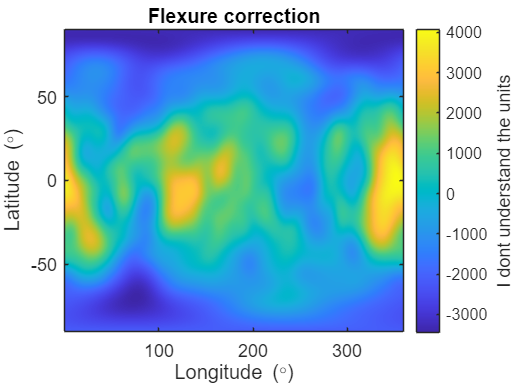

n = 1:size(sc,1);

%TODO: check equation below
D = 200e9*(Te_ref)^3/(12*(1-0.5^2));
PHI = (1 + D/(500*2/g_ref).*(2.*(n+1)./(2*R_ref)).^4).^(-1);

sc_flex = zeros(size(sc3));

for m = 1:size(sc3,2)
    sc_flex(:,m) = sc3(:,m).*PHI';
end

sc_flex;

mapf = GSHS(sc_flex,lonT,90-latT,160);

figure
imagesc(lonT,latT,mapf);cc=colorbar;
title("Flexure correction")
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'I dont understand the units','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)

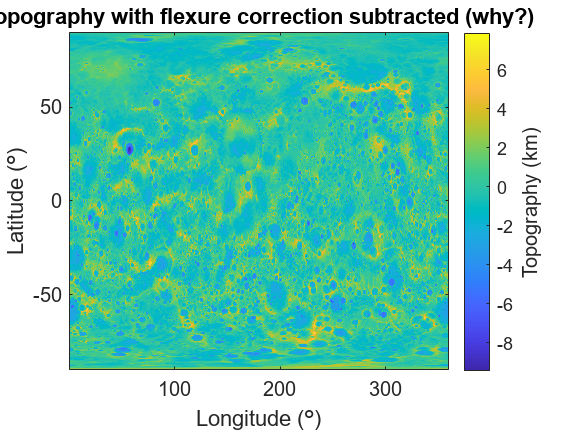



figure
imagesc(lonT,latT,(resized_topo_map-mapf)./1e3);cc=colorbar;
colormap("parula");
title("Topography with flexure correction subtracted (why?)")
xlabel('Longitude (\circ)','Fontsize',aa)
ylabel('Latitude (\circ)','Fontsize',aa)
ylabel(cc,'Topography (km)','Fontsize',aa)
set(gca,'YDir','normal','Fontsize',aa)